# Signals #1: sine vs noise, sampling theorem and signal acquisition

## Signals

Signals are taken from sensors which are plenty in surrounding us world and possess information about this world we would like to know. Signals are also generated by us and used for different purposes: for information transmision (telecommunication), knowledge acquisition (biomedicine), ...

## Sines and their sampling

*Pure deterministic* signals have shapes defined by means of known *math* *functions*: sinusoid, exponent, gaussoid, ... or by multiplications (sample-by-sample) of known functions, e.g. sinusoid by exponent, giving as a result damped sinusoid. *Complex deterministic* signals are sums (mixtures) of *pure* signals. Sinusoid is the best known (the most popular) deterministic signal. 

For example, sinusoidal signal, with amplitude (*strength*) $A_1=0.5$, frequency (*number of repetitions per one second*) $f_1=10$ Hz, and phase shift (*angle*) $\phi_1=\pi / 4$ radians, is defined by the following equation:


$$x_1(t)=0.5 \cdot \sin \left( 2\pi \cdot 10 \cdot t + \frac{\pi}{4} \right), \quad t \in [0, +\infty) ,$$


After using the following denotations: $dt=1 / f_{s}$ (sampling period, time interval between two signal samples, inverse of the sampling frequency $f_s$), $t=n \cdot dt = n / f_s$ (sampling moments), $n=0,1,2,...$ (indexes of samples), we obtain formula of discrete-time sinusoid:


$$x_1(n) = 0.5 \cdot \sin \left( 2\pi \frac{10}{f_{s}} n + \frac{\pi}{4} \right), \quad  n=0,1,2,...$$


**Analyze the Matlab code**. Run the code given below. Change values of  `A1,f1,p1`: observe change of the signal shape.

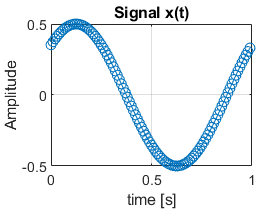

fs=100; Nx=100;                 % sampling frequency, number of samples
dt = 1/fs;                      % sampling period 
t = dt*(0:Nx-1);                % sampling times (many moments)
A1=0.5; f1=1; p1=pi/4;          % sine #1 amplitude, frequency and phase
x1 = A1 * sin(2*pi*f1*t+p1);    % sine as a first signal component
x = x1;                         % our choice: x = x1, x1 + 0.123*x2 + 0.456*x3 
figure; plot(t,x,'o-'); grid; title('Signal x(t)'); xlabel('time [s]'); ylabel('Amplitude');

Now generate the second signal $x_2(n)$ with different values of `A2,f2,p2`` and add it to `$x_1(n)$.

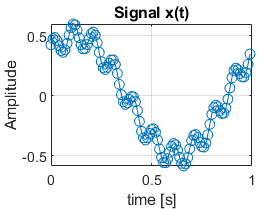

A2=0.1; f2=10; p2=pi/7;         % sine #2 amplitude, frequency and phase
x2 = A2 * sin(2*pi*f2*t+p1);    % sine as a second signal component
x = x1 + x2;                    % our choice: x = x1, x1 + 0.123*x2 + 0.456*x3 
figure; plot(t,x,'o-'); grid; title('Signal x(t)'); xlabel('time [s]'); ylabel('Amplitude');

## **Noises** 

*Random signals* have a form of noise. They are described by probability density functions (PDFs)  telling what noise values are prefered (are the most probable). Gaussian and uniform are typical PDF shapes.

**Analyze the Matlab code**. Run the below section. Note minimum and maximum values of signal `x1` and `x2`. Histogram shows us how many signal samples have values in predefined intervals. Change value of Nx. Is the Gaussian PDF becoming more "Gaussian"? 

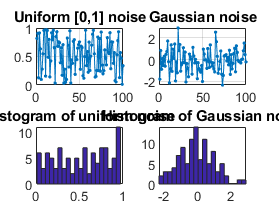

s1 = rand(1,Nx);    % s1 = 0.1*(2*(s1-0.5));  % uniform;  scaling to [-0.1,0.1]
s2 = randn(1,Nx);   % s2 = 0.1*s2;            % Gaussian; scaling to std=0.1
figure
subplot(221); plot(s1,'.-'); grid; title('Uniform [0,1] noise');
subplot(222); plot(s2,'.-'); grid; title('Gaussian noise');
subplot(223); hist(s1,20); title('Histogram of uniform noise');
subplot(224); hist(s2,20); title('Histogram of Gaussian noise');

Now add one noise, s1 or s2, to one sine, x1 or x2. Check all combinations. Scale noise componets, i.e. make them stronger or weaker.

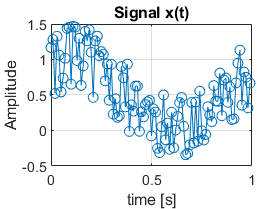

x = x1 + s1;                         % our choice: x = x1+s1, x1+s2, x2+s1, x2+s2 
figure; plot(t,x,'o-'); grid; title('Signal x(t)'); xlabel('time [s]'); ylabel('Amplitude');

## **Sampling theorem** 

Every real-value signal has to be sampled in such way that a sinusoid with the highest frequency, present in this signal, should posses more than two samples per its period, i.e.

$f_{s} > 2 \cdot f_{max}$.

If the sampling theorem is not fullfilled the high-frequency sine looks like a low-frequency one, for example if the signal frequency is equal $k \cdot f_{s} \pm f_1$ we have:


$$x_1(n) = A_1 \sin \left( 2\pi \frac{k \cdot f_{s} \pm f_1}{f_{s}}n + \phi_1 \right) = A_1 \sin \left( 2\pi k n \pm 2\pi \frac{f_1}{f_{s}}n + \phi_1 \right) = \pm A_1 \sin \left( 2\pi \frac{f_1}{f_{s}}n + \phi_1 \right)$$


**Analyze the Matlab code**. Run it for: 1) different multiplies of $$f_s$$, 2) $\pm f_1$, 3) sine and cosine.

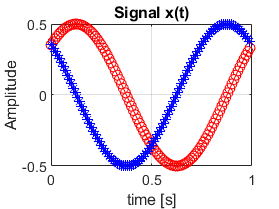

x1hf = A1 * sin(2*pi*(5*fs-f1)*t+p1);  % too high-frequency sine
figure; plot(t,x1,'ro-',t,x1hf,'b*-'); grid; title('Signal x(t)'); xlabel('time [s]'); ylabel('Amplitude');

## **Real-world signal acquisition**

**Analyze the Matlab code**. Let's record our own speech: 1) run the code, 2) press any key, 3) after 1 second, 4) say the word: "San Fransisco".

fs=16000; Nx=3*fs;                          % sampling rate, number of recorded samples               
Nbits=16; Nchans=1;                         % number of bits and audio channels
recorder = audiorecorder(fs,Nbits,Nchans);  % create the recorder
display('Press any .. say San Francisco'); pause; 

Press any .. say San Francisco


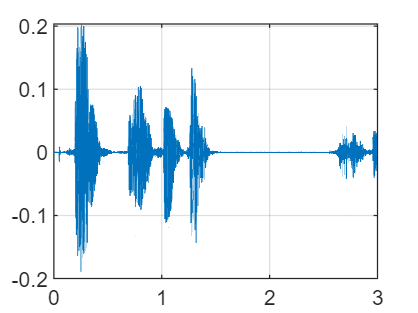

recordblocking( recorder, Nx/fs );          % record Nx/fs seconds of data
x = getaudiodata( recorder );               % get the samples
plot( 1/fs*(0:length(x)-1), x ); grid;      % plot speech x(t)

soundsc(x,fs);                              % listen to your own speech

Observe the signal. Does it consist of sum-of-sines-like and noisy-like fragments?

## **Inspection of different real-world signals**

Download, observe and play a few sounds taken from the webpage: [https://findsounds.com/](https://findsounds.com/)